## **Àlgebra lineal -**

## **Mètodes directes de resolució de sistemes lineal**

A = [1 2 1; -2 7 3; 1 -1 10]

A =      1     2     1
    -2     7     3
     1    -1    10


determinante

det(A)

ans = 114

inversa

inv(A)

ans =     0.6404   -0.1842   -0.0088
    0.2018    0.0789   -0.0439
   -0.0439    0.0263    0.0965


rango

rank(A)

ans = 3

transpuesta

A'

ans =      1    -2     1
     2     7    -1
     1     3    10


norma 1

norm(A,1)

ans = 14

norma infinit

norm(A, 'inf')

ans = 12

norma 2

norm(A,2)

ans = 10.6260

%eig calcula els valors propis
norma2 = sqrt(eig(A'*A))

norma2 =     1.4467
    7.4158
   10.6260


## **Matrius definides**

Matriz de zeros

zeros(4)

ans =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


Matriz de unos

ones(5)

ans =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


Matriz identidad

eye(4)

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Matriz donde los valores van de 5 a 5^2 y la suma de las finals y columass son las mismas

magic(5)

ans =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


diagonal de la matriz

v = diag(A)

v =      1
     7
    10


diag(v)

triangular de la matriz menor

tril(A)

ans =      1     0     0
    -2     7     0
     1    -1    10


triangular de la matriz menos uno

tril(A,-1)

ans =      0     0     0
    -2     0     0
     1    -1     0


 triangular de la matriz superior

triu(A)

ans =      1     2     1
     0     7     3
     0     0    10


triangular de la matriz menos uno

triu(A,-1)

ans =      1     2     1
    -2     7     3
     0    -1    10


# Mètodes directes

A = triu(rand(6))

A =     0.3111    0.4389    0.6028    0.4242    0.9289    0.9631
         0    0.1111    0.7112    0.5079    0.7303    0.5468
         0         0    0.2217    0.0855    0.4886    0.5211
         0         0         0    0.2625    0.5785    0.2316
         0         0         0         0    0.2373    0.4889
         0         0         0         0         0    0.6241



b = ones(6,1)

b =      1
     1
     1
     1
     1
     1



x = backsubs(A,b)

x =    -5.6658
    2.4199
   -1.4156
    0.3841
    0.9128
    1.6024



r = norm(b-A*x,'inf')

r = 2.2204e-16


x = forward(A,b)

x =     3.2144
    8.9993
    4.5096
    3.8098
    4.2144
    1.6024



r = norm(b-A*x,'inf')

r = 13.7419

# Eliminació Gaussiana

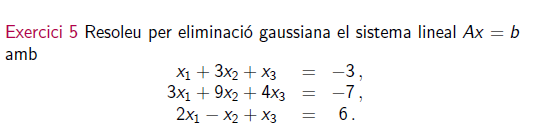

A = [1 3 1; 3 9 4; 2 -1 1]

A =      1     3     1
     3     9     4
     2    -1     1


b = [-3; -7; 6]

b =     -3
    -7
     6


[L,U,P] = lu(A)

L =     1.0000         0         0
    0.6667    1.0000         0
    0.3333   -0.0000    1.0000


U =     3.0000    9.0000    4.0000
         0   -7.0000   -1.6667
         0         0   -0.3333


P =      0     1     0
     0     0     1
     1     0     0



% 1) Ly = Pb
y = forward(L, P*(b))

y =    -7.0000
   10.6667
   -0.6667


% 2) Ux = y
x = backsubs(U,y)

x =     1.0000
   -2.0000
    2.0000



% comprobar residuo

r = b - A*x

r = 	1.0e+-14 *

    0.0444
    0.1776
    0.1776




% opertacion de matlab

A\b

ans =     1.0000
   -2.0000
    2.0000


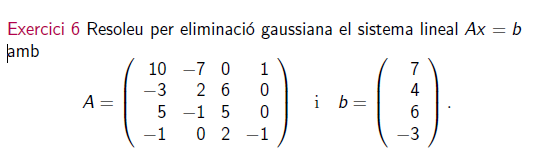

A = [10 -7 0 1; -3 2 6 0; 5 -1 5 0; -1 0 2 -1]

A =     10    -7     0     1
    -3     2     6     0
     5    -1     5     0
    -1     0     2    -1


b= [7; 4; 6; -3]

b =      7
     4
     6
    -3


[L,U,P] = lu(A)

L =     1.0000         0         0         0
    0.5000    1.0000         0         0
   -0.3000   -0.0400    1.0000         0
   -0.1000   -0.2800    0.5484    1.0000


U =    10.0000   -7.0000         0    1.0000
         0    2.5000    5.0000   -0.5000
         0         0    6.2000    0.2800
         0         0         0   -1.1935


P =      1     0     0     0
     0     0     1     0
     0     1     0     0
     0     0     0     1



% 1) Ly = Pb
y = forward(L, P*(b))

y =     7.0000
    2.5000
    6.2000
   -5.0000


% 2) Ux = y
x = backsubs(U,y)

x =     0.4324
    0.2162
    0.8108
    4.1892



% comprobar residuo

r = b - A*x

r = 	1.0e+-15 *

         0
         0
         0
   -0.8882




% opertacion de matlab

A\b

ans =     0.4324
    0.2162
    0.8108
    4.1892


# Factorització Txoleski

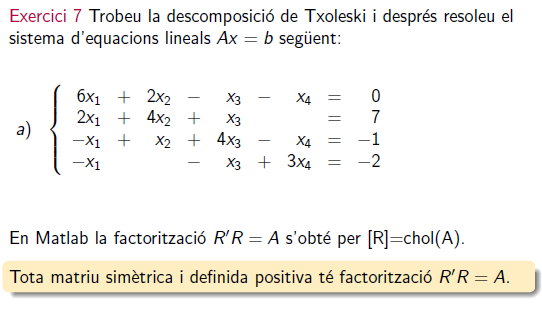

A = [6 2 -1 -1; 2 4 1 0; -1 1 4 -1; -1 0 -1 3]

A =      6     2    -1    -1
     2     4     1     0
    -1     1     4    -1
    -1     0    -1     3


b = [0 7 -1 2]'

b =      0
     7
    -1
     2


isequal(A',A)

ans = logical
   1


%R'Rx = b
R = chol(A)

R =     2.4495    0.8165   -0.4082   -0.4082
         0    1.8257    0.7303    0.1826
         0         0    1.8166   -0.7156
         0         0         0    1.5126



%1) R'y = b
y = forward(R',b)

y =          0
    3.8341
   -2.0918
   -0.1302


%2) UX = y 
x = backsubs(R,y)

x =    -1.0728
    2.5828
   -1.1854
   -0.0861


r = b-A*x

r = 	1.0e+-14 *

    0.1041
   -0.1776
    0.0222
    0.0444


% opertacion de matlab
A\b

ans =    -1.0728
    2.5828
   -1.1854
   -0.0861


# Factorització QR

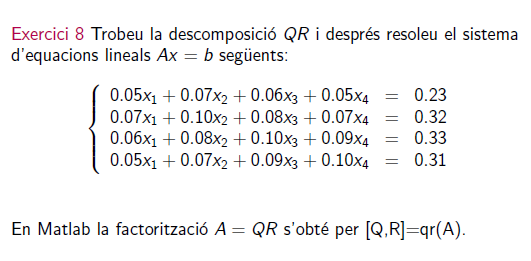

A = [5 7 6 5; 7 10 8 7; 6 8 10 9; 5 7 9 10]/100

A =     0.0500    0.0700    0.0600    0.0500
    0.0700    0.1000    0.0800    0.0700
    0.0600    0.0800    0.1000    0.0900
    0.0500    0.0700    0.0900    0.1000


b = [23; 32; 33; 32]/100

b =     0.2300
    0.3200
    0.3300
    0.3200


%Q*R = A
[Q,R] = qr(A)

Q =    -0.4303   -0.0844   -0.3695   -0.8192
   -0.6025   -0.5739   -0.2571    0.4915
   -0.5164    0.8102   -0.1285    0.2458
   -0.4303   -0.0844    0.8837   -0.1638


R =    -0.1162   -0.1618   -0.1644   -0.1532
         0   -0.0044    0.0224    0.0201
         0         0    0.0239    0.0403
         0         0         0   -0.0008


%1) Rx = Q'b
x = backsubs(R,Q'*b)

x =    11.0000
   -5.0000
   -2.0000
    3.0000


%comprobar que el residuo es 0
r = b -A*x

r = 	1.0e+-15 *

   -0.1110
         0
   -0.0555
    0.0555


# Vector residu

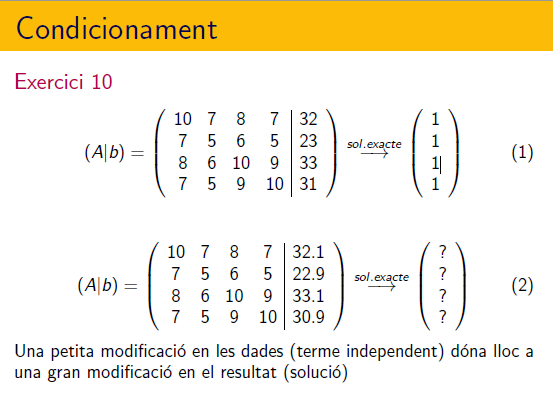

A = [10 7 8 7 ; 7 5 6 5 ; 8 6 10 9; 7 5 9 10]

A =     10     7     8     7
     7     5     6     5
     8     6    10     9
     7     5     9    10


b = [32 23 33 31]'

b =     32
    23
    33
    31


bb=[32.1 22.9 33.1 30.9]'

bb =    32.1000
   22.9000
   33.1000
   30.9000


b-bb

ans =    -0.1000
    0.1000
   -0.1000
    0.1000


norm(b-bb,'inf')

ans = 0.1000

x = A\b

x =     1.0000
    1.0000
    1.0000
    1.0000


y = A\bb

y =     9.2000
  -12.6000
    4.5000
   -1.1000


r = bb-A*y

r = 	1.0e+-13 *

    0.1421
    0.1066
    0.0711
    0.1066


cond(A),rcond(A), det(A)

ans = 2.9841e+03

ans = 2.2282e-04

ans = 1.0000


%comprobació cota error
c1 = cond(A,'inf')*norm(b-A*y,'inf')/norm(b,'inf')

c1 = 13.6000


c2 = norm(x-y, 'inf')/norm(x,'inf')

c2 = 13.6000

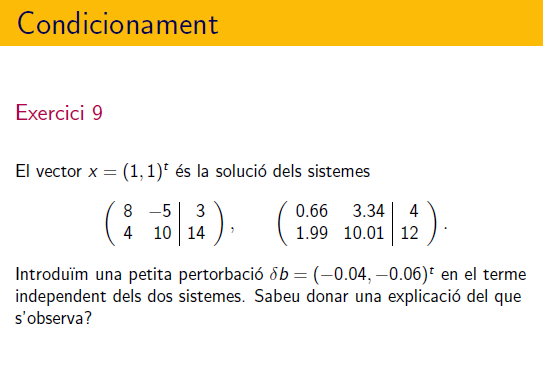

%a)
A= [8 -1; 4 10]

A =      8    -1
     4    10


b = [3 14]'

b =      3
    14


bb = b+[-0.04 -0.06]'

bb =     2.9600
   13.9400


rcond(A), det(A)

ans = 0.7500

ans = 84

x = A\bb, y = A\bb

x =     0.5183
    1.1867


y =     0.5183
    1.1867


%b)
A = [0.66 3.34; 1.99 10.01]

A =     0.6600    3.3400
    1.9900   10.0100


b = [4 12]'

b =      4
    12


bb = b+[-0.04 -0.06]'

bb =     3.9600
   11.9400


rcond(A), det(A)

ans = 2.4969e-04

ans = -0.0400

x = A\bb, y = A\bb

x =     6.0000
    0.0000


y =     6.0000
    0.0000


function x = forward(L,x)
% FORWARD. Forward elimination.
% For lower triangular L, x = forward(L,b) solves L*x = b.
[n,n] = size(L);
x(1) = x(1)/L(1,1);
for k = 2:n
   j = 1:k-1;
   x(k) = (x(k) - L(k,j)*x(j))/L(k,k);
end
end

% ------------------------------

function x = backsubs(U,x)
% BACKSUBS.  Back substitution.
% For upper triangular U, x = backsubs(U,b) solves U*x = b.
[n,n] = size(U);
x(n) = x(n)/U(n,n);
for k = n-1:-1:1
   j = k+1:n;
   x(k) = (x(k) - U(k,j)*x(j))/U(k,k);
end
end